# Modelo Longitudinal

Diseño de controlador SAS y CAS

clear; clc; close all; 

Cargamos el modelo desacoplado longitudinal

load('modelo_lin.mat', 'longmod')

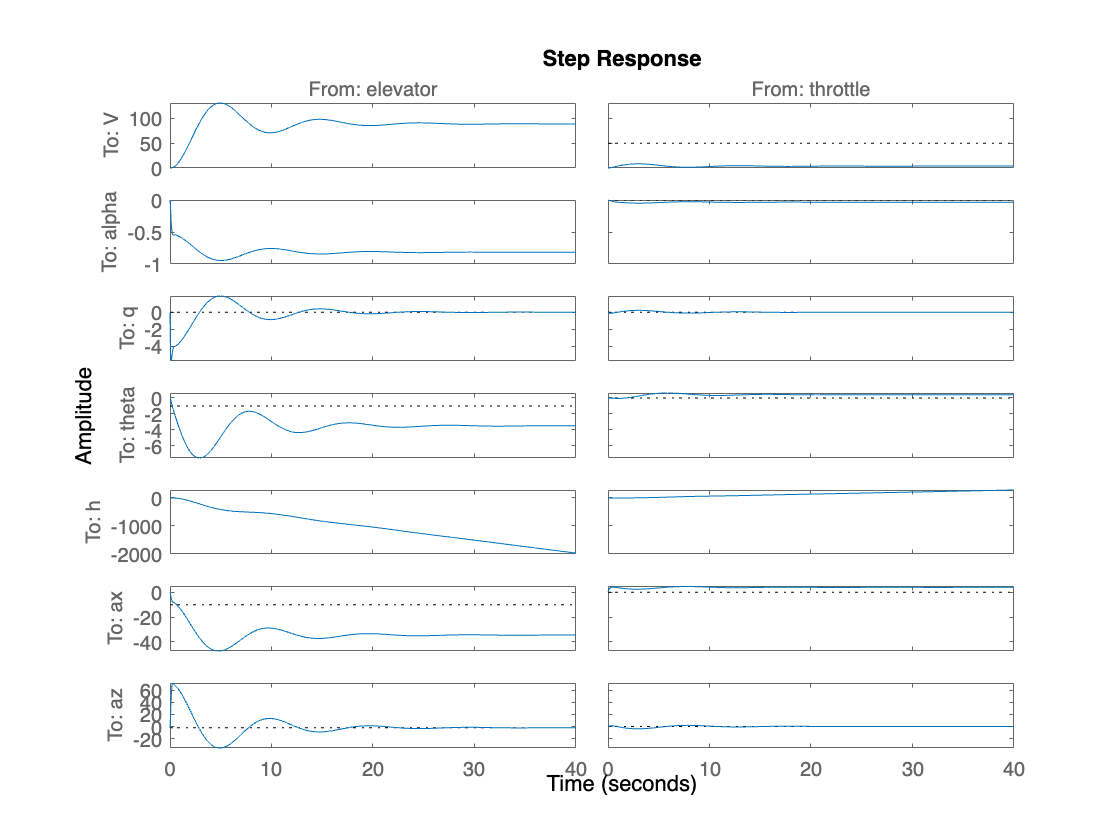

step(longmod); 

Contamos con un sistem lineal MIMO de 2 entradas y 7 salidas 

#### Entradas: 

Elevator, Throttle

#### Salidas: 

V, q, theta, h, ax, az. 

## Diseño de sistema de estabilidad (SAS)

Para el diseño del SAS, se busca generar una amortiguación por velocidad angular para la posición. Un regulador de velocidad por control proporcional. Tomamos entonces la función de transferencia de Elevator al pitch-rate (q) 


$$G\left(s\right)=\;\frac{Q\left(s\right)}{\textrm{Elevator}\left(s\right)}$$


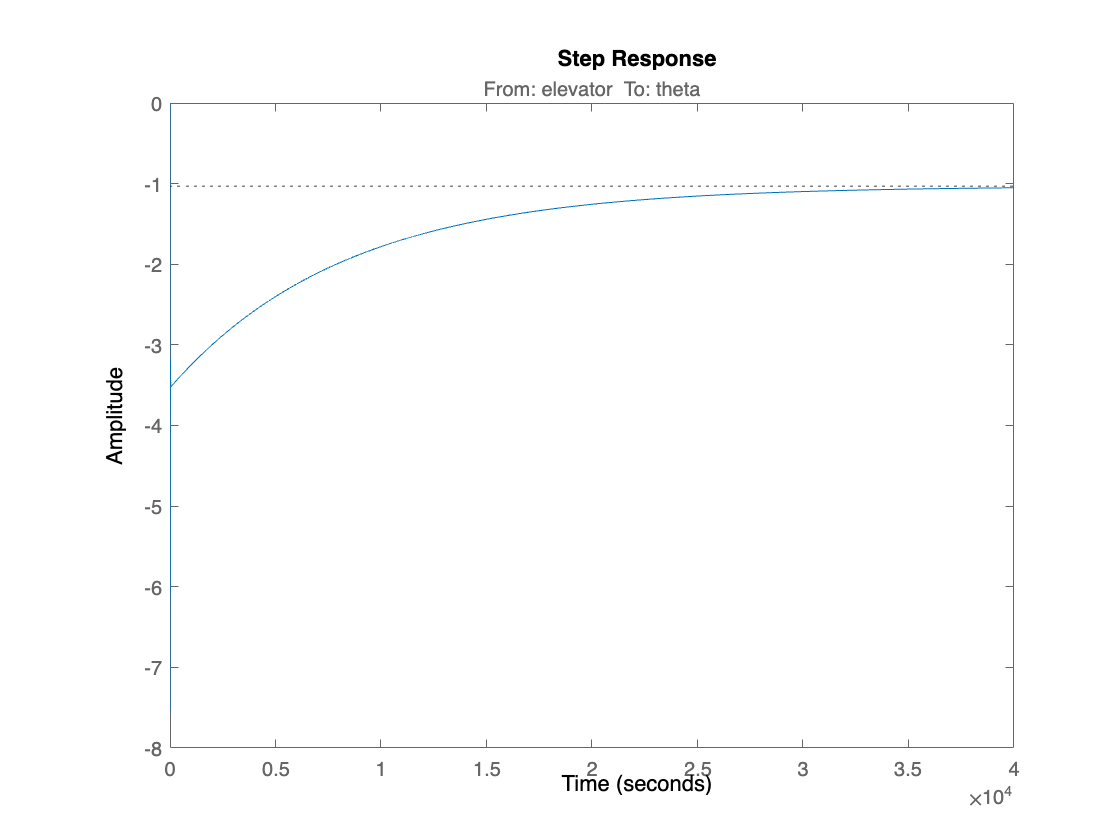

model_tf = tf(longmod); % tf de modelo completo 
L_velocidad = model_tf(3, 1); % td de elevator a pitch-rate (q)
L_posicion = model_tf(4, 1); % td de elevator a pitch-rate (q)

step(L_posicion)

Lugar de las raíces para encontrar ganancia proporcional que ajuste las perturbaciones. Menor damping posible 

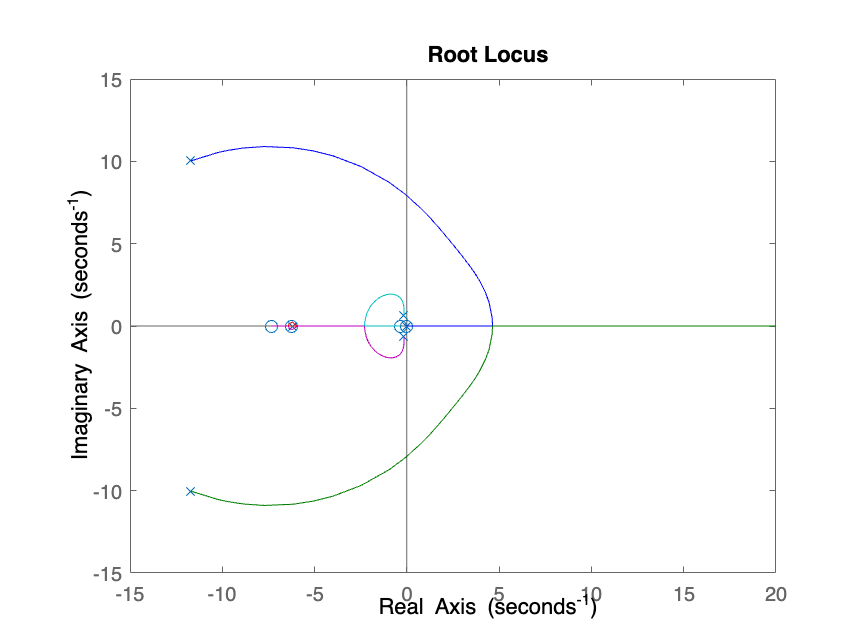

rlocus(L); 

Con una ganancia de K = 0.02 se obtiene un sobrepico aceptable < 5%

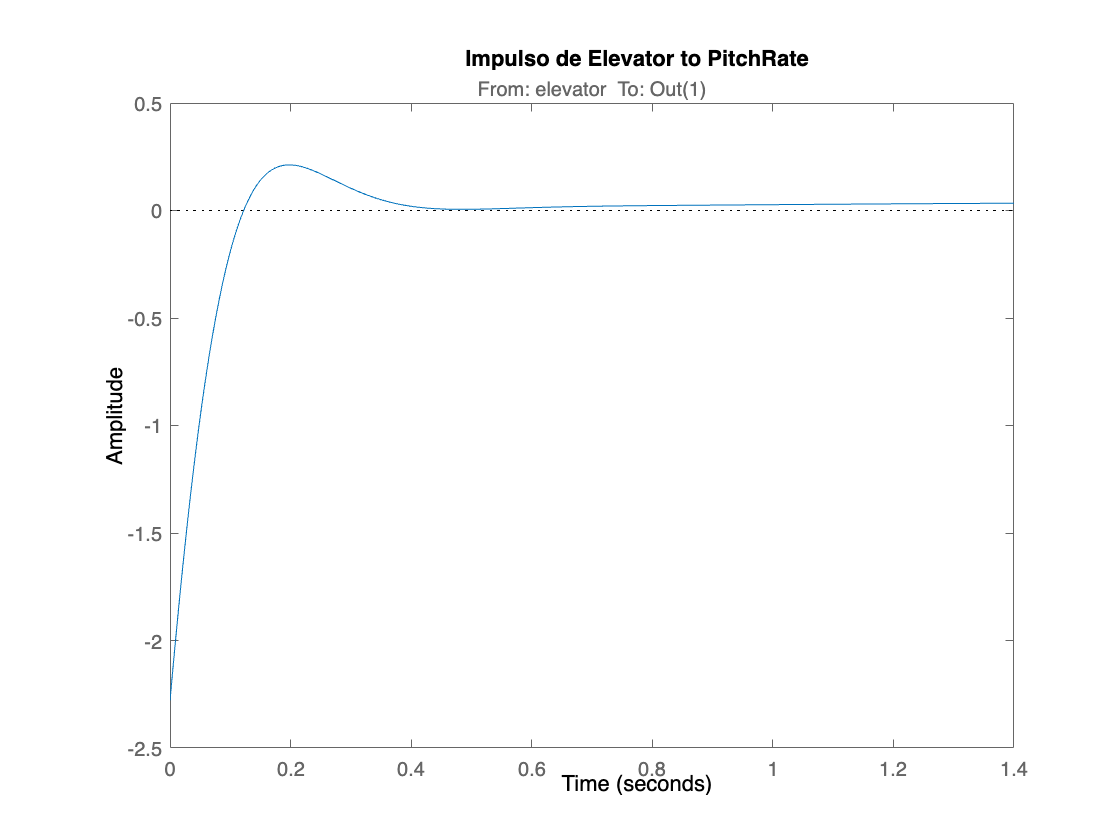

% Prueba de Feedback SISO
k = 0.017; 
T_siso = feedback(k * L, 1); 
impulse(T_siso)
title("Impulso de Elevator to PitchRate"); 

**Feedback MIMO: **Retroalimentamos el sistema con el pitch rate para el primer lazo, 

I_channels = [1, 2]; % elevator, throttle
O_channels = [3, 3]; % pitch_rate
% K = eye(2) * -4; 
K = [k, 0; 0, 0]

K =     0.0170         0
         0         0


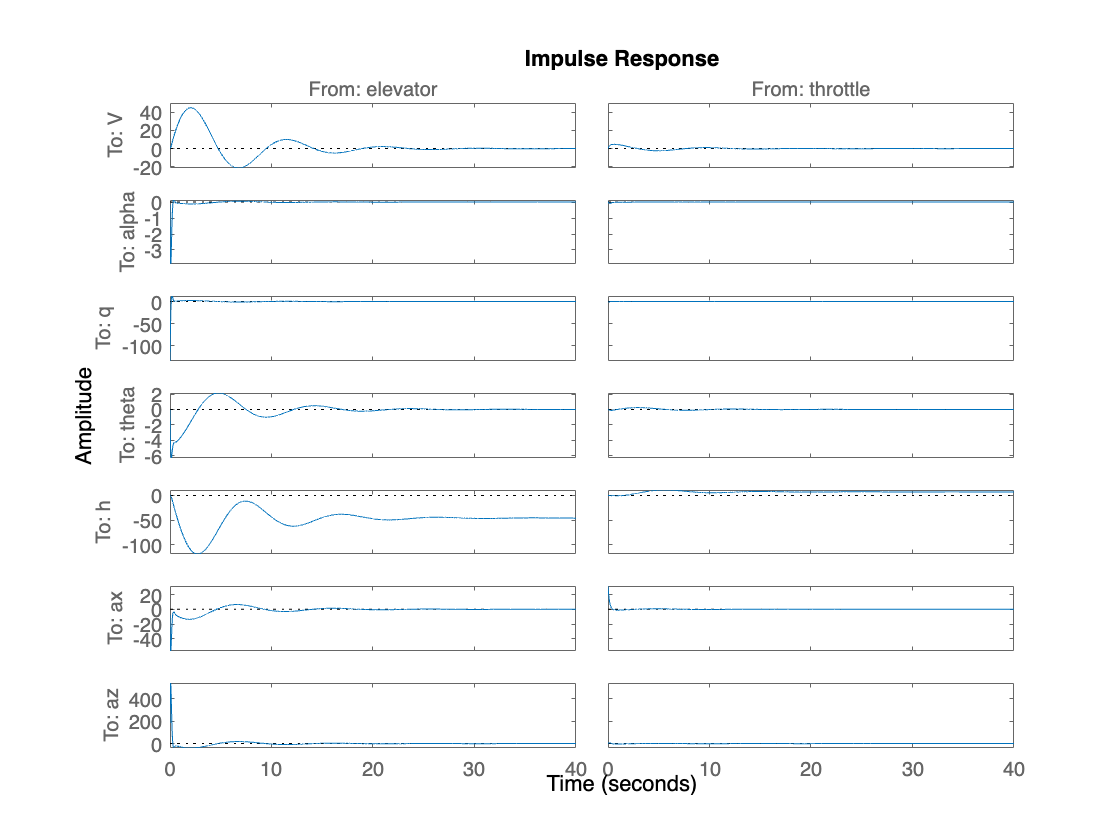

CL1 = feedback(longmod, K, I_channels, O_channels, -1); 
impulse(CL1)

## Diseño de sistema de Control (CAS)

Aquí tomamos como retroalimentacion el estado de posición angular de cabeceo (pitch) $\theta$ para hacer un seguimiento de posición. Para esto hacemos un segundo lazo de retroalimentacion tomando la posicion angular como señal retroalimentada. 

L_pitch_control = CL1(4, 1); 
tf(L_pitch_control)

ans =
 
  From input "elevator" to output "theta":
          -134.1 s^4 - 1869 s^3 - 6807 s^2 - 2268 s - 0.07966
  --------------------------------------------------------------------
  s^6 + 27.67 s^5 + 361.1 s^4 + 1493 s^3 + 599.1 s^2 + 642 s + 0.07726
 
Continuous-time transfer function.



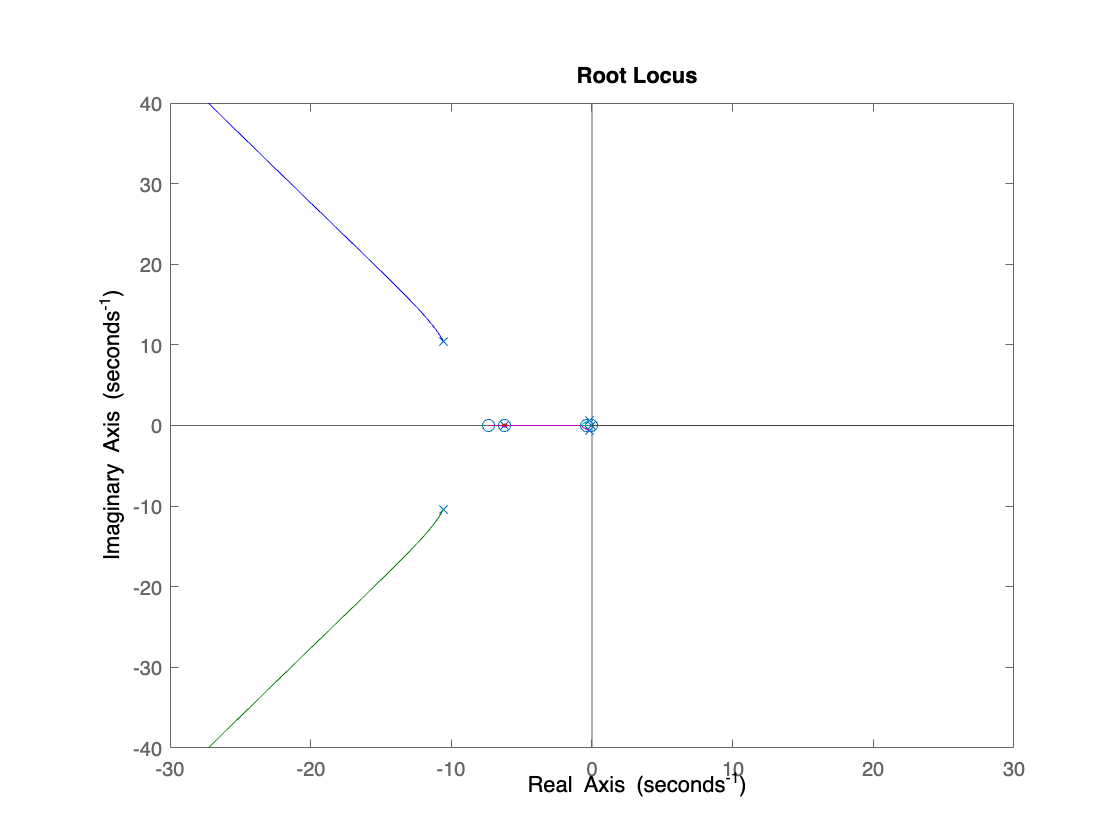

s = tf('s'); 
rlocus(1/s * L_pitch_control);

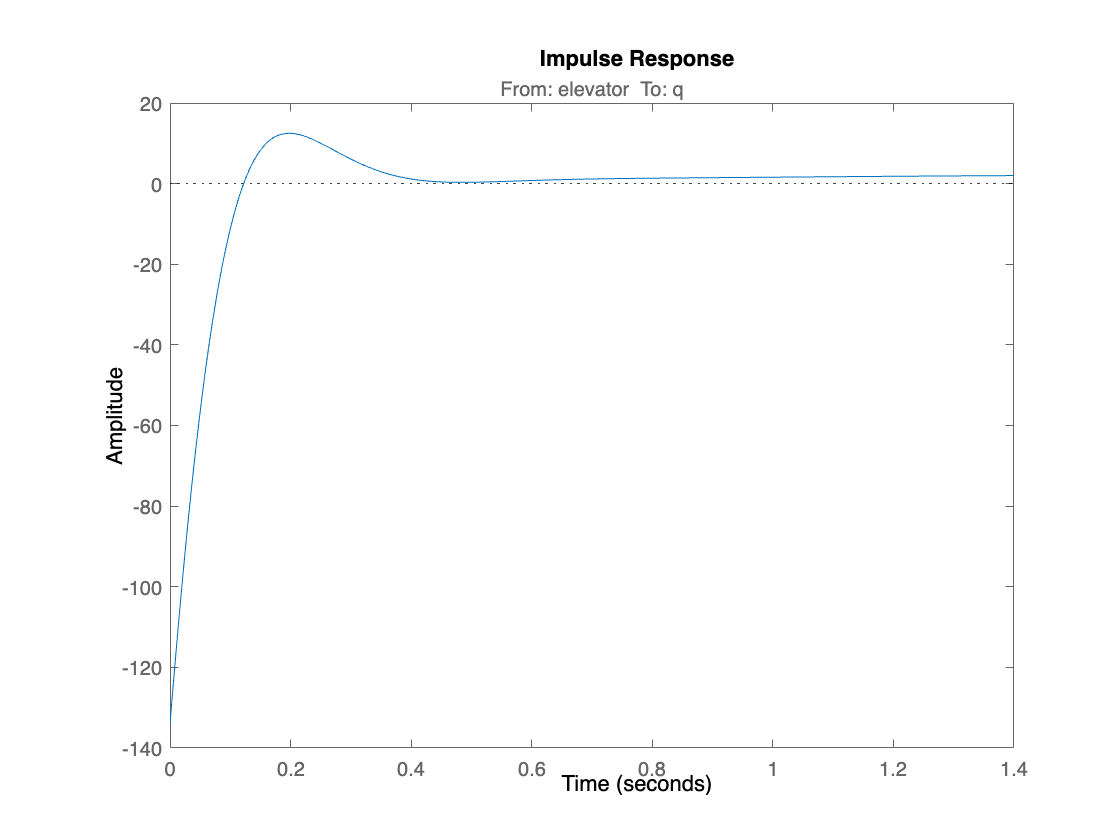

g_elevator_pitchrate = tf(CL1(3, 1)); 
impulse(g_elevator_pitchrate)

## Revisión de Desempeño

## Revisión de Robustez 

## Comentarios y Conclusiones 